clc;
clear;
M =4;
rng(1);
b_tx = bit_gen(10,2)

b_tx =      0     0
     1     1
     0     0
     0     1
     0     0
     0     1
     0     0
     0     1
     0     0
     1     0


b_gray = gray_code(2)

b_gray =      0     0
     0     1
     1     1
     1     0


sym_idx=symidx(b_tx,b_gray)

sym_idx =      0
     2
     0
     1
     0
     1
     0
     1
     0
     3


[cons, Es_avg] = constellation(4, 'pam')

cons =    -1.3416
   -0.4472
    0.4472
    1.3416


Es_avg = 1

sym_mode = symmode(sym_idx,cons)

sym_mode =    -1.3416
    0.4472
   -1.3416
   -0.4472
   -1.3416
   -0.4472
   -1.3416
   -0.4472
   -1.3416
    1.3416


fs = 1;
smpl_per_symbl = 8;
[tx_out, cons] = pulse_modulation(sym_idx, 'pam', ...
                                            M, fs, smpl_per_symbl, ...
                                               'triangular' , 'kron')

tx_out =          0
   -0.2023
   -0.4045
   -0.6068
   -0.8090
   -0.6068
   -0.4045
   -0.2023
         0
    0.0674


cons =    -1.3416
   -0.4472
    0.4472
    1.3416


[tx_out_conv, cons_conv] = pulse_modulation(sym_idx, 'pam', ...
                                            M, fs, smpl_per_symbl, ...
                                               'triangular' , 'conv')         

tx_out_conv =          0
   -0.2023
   -0.4045
   -0.6068
   -0.8090
   -0.6068
   -0.4045
   -0.2023
         0
    0.0674


cons_conv =    -1.3416
   -0.4472
    0.4472
    1.3416


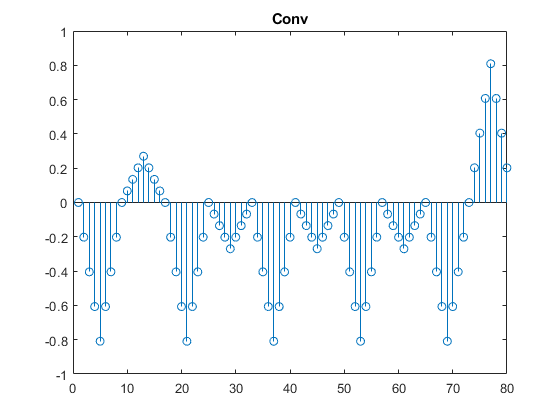

                                           
stem(1:80,tx_out_conv)  
title('Conv')

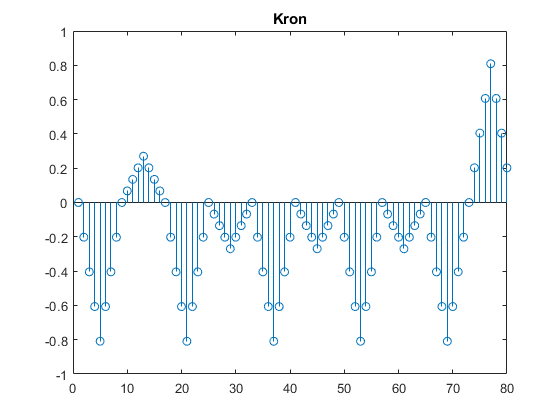

stem(1:80,tx_out)
title('Kron')

p=pulse_shape('triangular',1,8);

[rx_sym_corr] = corr_match(tx_out, p, smpl_per_symbl, 'correlator')

rx_sym_corr =    -1.3416
    0.4472
   -1.3416
   -0.4472
   -1.3416
   -0.4472
   -1.3416
   -0.4472
   -1.3416
    1.3416


[rx_sym_matched] = corr_match(tx_out, p, smpl_per_symbl, 'matched_filter')

rx_sym_matched =    -1.3416
    0.4472
   -1.3416
   -0.4472
   -1.3416
   -0.4472
   -1.3416
   -0.4472
   -1.3416
    1.3416


[det_sym] = min_dist_detector(rx_sym_matched, cons)

det_sym =      1
     3
     1
     2
     1
     2
     1
     2
     1
     4


[det_sym_idx, rx_sym] = pulse_demodulation(tx_out, 'pam', M, fs, ...
                                    smpl_per_symbl, 'triangular' , 'correlator')                                

det_sym_idx =      1
     3
     1
     2
     1
     2
     1
     2
     1
     4


rx_sym =    -1.3416
    0.4472
   -1.3416
   -0.4472
   -1.3416
   -0.4472
   -1.3416
   -0.4472
   -1.3416
    1.3416


b1 = b_gray(det_sym_idx,1)

b1 =      0
     1
     0
     0
     0
     0
     0
     0
     0
     1


b2 = b_gray(det_sym_idx,2)

b2 =      0
     1
     0
     1
     0
     1
     0
     1
     0
     0


det_bit = [b1 b2]

det_bit =      0     0
     1     1
     0     0
     0     1
     0     0
     0     1
     0     0
     0     1
     0     0
     1     0


det_bit_dec = det_bit(:,1)*2 + det_bit(:,2)

det_bit_dec =      0
     3
     0
     1
     0
     1
     0
     1
     0
     2


function [b] = bit_gen(N,k)
b = randi([0 1],N,k);
end

function [b_gray] = gray_code(k)

if k == 1
    b_gray = [0;1];
else
    z=zeros(2^(k-1),1);
    o = ones(2^(k-1),1);
    rec = gray_code(k-1);
    recB =  rec(end:-1:1,:);
    b_gray = [z,rec;o,recB];
end
end

function sym_idx = symidx(b_tx,b_gray)
sym_idx=zeros(size(b_tx,1),1);
for i=1:size(b_tx,1)
    a = prod(b_tx(i,:)==b_gray,2);
    sym_idx(i) = find(a==1) - 1;
end
end

function [cons, Es_avg] = constellation(M, modulation)
switch modulation
    case 'pam'
        m = transpose(1:M);
        cons = 2 * m - 1 - M;
        Es_avg = mean(abs(cons).^2);
        cons = cons / sqrt(Es_avg);
        Es_avg = mean(abs(cons).^2);
end
end

function [p, t] = pulse_shape(pulse_name, fs, smpl_per_symbl, varargin)
t = transpose(0:1/fs:(smpl_per_symbl-1)/fs);
Ts = smpl_per_symbl/fs;
switch pulse_name
    case 'triangular'
        p = max((Ts/2)-abs(t-(Ts/2)), 0);
        p = p / sqrt(sum(abs(p).^2));
end
end

function sym_mode = symmode(sym_idx,cons) 
for i=1:size(sym_idx,1)
    sym_mode(i,1) = cons(sym_idx(i)+1);
end
end

function [tx_out, cons] = pulse_modulation(sym_idx, modulation, ...
                                            M, fs, smpl_per_symbl, ...
                                               pulse_name , pulse_shape_mode, ...
                                               varargin)
[cons, Es_avg] = constellation(M, modulation);                                         
[p, t] = pulse_shape(pulse_name, fs, smpl_per_symbl, varargin);
sym_mode = symmode(sym_idx,cons);
sym_mode_up = upsample(sym_mode,smpl_per_symbl);
sym_mode_up = sym_mode_up(1:end-(smpl_per_symbl-1),1);
switch (pulse_shape_mode)   
    case 'kron'
        tx_out=kron(sym_mode,p);
    case 'conv'
        tx_out=conv(sym_mode_up,p);
end                                        
end

function [rx_sym] = corr_match(rx_smpl, p, smpl_per_symbl, rx_mode)
rx_sym = zeros(10,1);
switch rx_mode
    case 'correlator'
        for i=1:10 
          corrx = p'*rx_smpl(smpl_per_symbl*(i-1)+1:smpl_per_symbl*(i));
          rx_sym(i,1) = corrx;  
        end
    case 'matched_filter'
        r = conv(p(end:-1:1,1),rx_smpl);
        for (j=1:10)
         rx_sym(j,1)= r(j*smpl_per_symbl,1);   
        end
        
end
end

function [det_sym] = min_dist_detector(rx_sym,constellation)
dist = (rx_sym - constellation.').^2;
[~,det_sym] =  min(dist,[],2);
end


function [det_sym_idx, rx_sym] = pulse_demodulation(rx_smpl, modulation, M, fs, ...
                                    smpl_per_symbl, pulse_name , rx_mode, varargin)

                                
t = transpose(0:1/fs:(smpl_per_symbl-1)/fs);
Ts = smpl_per_symbl/fs;
switch pulse_name
    case 'triangular'
        p = max((Ts/2)-abs(t-(Ts/2)), 0);
        p = p / sqrt(sum(abs(p).^2));
end

rx_sym = zeros(10,1);
switch rx_mode
    case 'correlator'
        for i=1:10 
          corrx = p'*rx_smpl(smpl_per_symbl*(i-1)+1:smpl_per_symbl*(i));
          rx_sym(i,1) = corrx;  
        end
    case 'matched_filter'
        r = conv(p(end:-1:1,1),rx_smpl);
        for (j=1:10)
         rx_sym(j,1)= r(j*smpl_per_symbl,1);   
        end
        
end

switch modulation
    case 'pam'
        m = transpose(1:M);
        cons = 2 * m - 1 - M;
        Es_avg = mean(abs(cons).^2);
        cons = cons / sqrt(Es_avg);
        Es_avg = mean(abs(cons).^2);
end


dist = (rx_sym - cons.').^2;
[~,det_sym_idx] =  min(dist,[],2);

end